clear all
close all

addpath("Immagini\07_snr")

binning = [1 2 4 8];
images = ["soft_b1.asc" "soft_b2.asc" "soft_b4.asc" "soft_b8.asc"];
noises = ["soft_b1_buio.asc" "soft_b2_buio.asc" "soft_b4_buio.asc" "soft_b8_buio.asc"];

SNR_hard = [];
error_hard = [];

SNR_soft = [];
error_soft = [];

for i=1:length(binning)
    [sh, eh] = signal_to_noise_hard(images(i), noises(i), binning(i));
    SNR_hard = [SNR_hard; sh];
    error_hard = [error_hard; eh];

    [ss, es] = signal_to_noise_soft(images(1), noises(1), binning(i));
    SNR_soft = [SNR_soft; ss];
    error_soft = [error_soft; es];
end

SNR_soft = 235.7414

SNR_soft =   235.7414
  457.8835


SNR_soft =   235.7414
  457.8835
  942.2361


SNR_soft = 1.0e+03 *

    0.2357
    0.4579
    0.9422
    1.8457


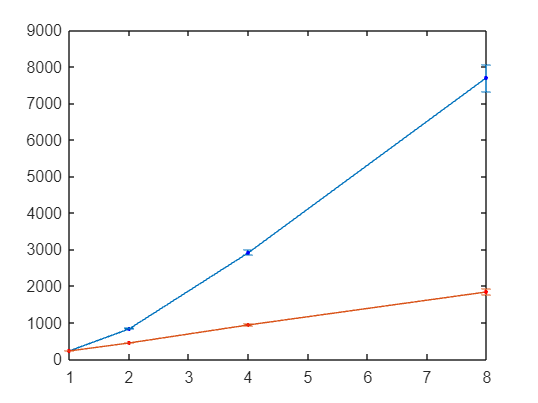

errorbar(binning, SNR_hard, error_hard, "-o", "MarkerSize", 2, "MarkerEdgeColor", "blue", "MarkerFaceColor", "blue")
hold on
errorbar(binning, SNR_soft, error_soft, "-o", "MarkerSize", 2, "MarkerEdgeColor", "red", "MarkerFaceColor", "red")
hold off